# Automatic Flight Control of F8-Crusader

## Control Objective: 

To track a specific trajectory, $r\left(t\right)$, of the angle of attack, $x_1$.

## System: 

States: $x_1$ is the angle of attack (AoA) (rad), $x_2$ is the pitch angle (rad), $x_3$ is the pitch rate (rad/s ) 

Control input: $u$ is the control input representing the tail deflection angle (rad)

Reference: $r\left(t\right)$ is the commanded angel of attack to be tracked

Outputs: assume full-state feedback (all states can be measured directly)

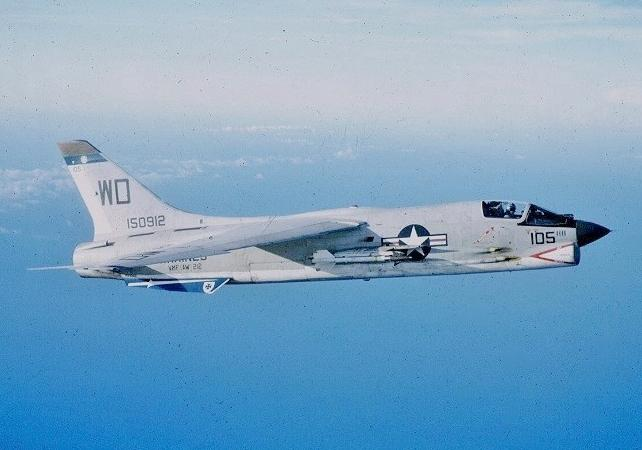

## Setting of Workflow

clear all, close all, clc;

figpath = fullfile('FIGURES', 'F8');
datapath = fullfile('DATA', 'F8');
paths = {figpath, datapath};

for p = 1:length(paths)
    if ~exist(paths{p}, 'dir')
        mkdir(paths{p});
    end
end

addpath(fullfile('utils'));
addpath(fullfile('EX_FLIGHT_CONTROL_F8'));

SystemModel = 'F8';
Nvar = 3; % number of states
Nctrl = 1; % number of control inputs

## Generating Training Data

InputSignalType = 'sine3'; % define type of control input to apply, u %'sine2'; sine3, %prbs; noise; sine2; sphs; 
ONLY_TRAINING_LENGTH = 1; % ?
ENSEMBLE_DATA = 0; % don't use ensemble learning methods
% generate training and validation data and plot control input and state
% time series
getTrainingData 
eps = 0; % zero noise
u = u'; % control input time series

tspanV = [tspan(end):dt:200]; % time span over validation phase

% Add noise
%eps = 0.05*std(x(:,1)); % define noise to add to true function values
%x = x + eps*randn(size(x));    

## Reference Model

% generate control input signal
forcing = @(x, t) (0.5 * sin(5*t) .* sin(.5 * t) + 0.1).^3;

% true trajectory over validation phase for given control input signal
[tB_Ref, xB_Ref] = ode45(@(t,x) F8Sys(t, x, forcing(x,t)), tspanV, x(end,:), options);
u_valid = forcing(0, tB_Ref)';
t_valid = tspanV;

## SINDYc Modelling

We take $m$ ***snapshots*** in time of the state $\mathbf{x}$, the control input $\mathbf{u}$ and the time derivatives $\mathbf{\dot{x}}$:

$\mathbf{X} = [\mathbf{x_1} \quad \mathbf{x_2} \cdots \mathbf{x_m}] \in \mathbb{R}^{n \times m}$ , $\mathbf{U} = [\mathbf{u_1} \quad \mathbf{u_2} \cdots \mathbf{u_m}] \in \mathbb{R}^{p \times m}$ and $\mathbf{\dot{X}} = [\mathbf{\dot{x}_1} \quad \mathbf{\dot{x}_2} \cdots \mathbf{\dot{x}_m}] \in \mathbb{R}^{n \times m}$

where $n=3$ and $p=1$in our case.

We consider a ***library of candidate functions*** and evaluate it at $\mathbf{X}$and $\mathbf{U}$:


$$\mathbf{\Theta}(\mathbf{X}, \mathbf{U})$$


which will have $m$ rows corresponding to each snapshot in time, and in our case includes terms of the form $x_1^ax_2^bx_3^c$ for all combinations of powers $a,b,c = [0, 1, 2]$, where $\sigma$ is the number of canditate functions, which equals to $3*3*3 = 27$ in our case.

*The English version: *We try to guess what sort of terms could be included in the true dynamic system $\mathbf{\dot{x}} = f(\mathbf{x}, \mathbf{u})$, find the value of these terms for the state and control input at each of our $m$ measurements over time, and put them all into a matrix $\mathbf{\Theta}$

We assume that the system can be modeled as a*** sparse linear combination*** of these candidate function:


$$\mathbf{\dot{X}} = \mathbf{\zeta} \mathbf{\Theta}^T(\mathbf{X}, \mathbf{U})$$


such that most of the coefficients $\mathbf{\zeta}$ are zero and their corresponding candidate term in $\mathbf{\Theta}$ is not included in the linear combination model.

These $k$th row of the coefficients matrix $\mathbf{\zeta}$, corresponding to the $k$th state in $\mathbf{\dot{x}}$ and the $k$th row in $\mathbf{\dot{X}}$ can be computed by minimizing the squared 2-norm error between the model and the measured values (first term) and minimizing the 1-norm of the coefficients to promote sparsity (second term).

*The English version: *For each of our $m$ measurements of the state derivative $\mathbf{\dot{x}}$ in time, the $k \in [1, 2, \cdots, n]$th states across time can be approximated by $\dot{X}_k \approx \mathbf{\zeta}_k \theta^T(\mathbf{X}, \mathbf{U})$if we let most of the terms in $\mathbf{\zeta}_k$ go to zero. 


$$\mathbf{\zeta}_k = \arg\min_{\mathbf{\tilde{\zeta}}_k} \frac{1}{2}\Vert \mathbf{\dot{X}}_k - \mathbf{\tilde{\zeta}}_k \theta^T(\mathbf{X}, \mathbf{U}) \Vert_2^2 + \lambda \Vert \mathbf{\tilde{\zeta}}_k \Vert_1$$


*The Goal: *Find $\mathbf{\zeta}$ with many zero terms.

### Computing SINDYc model

% Parameters
ModelName = 'SINDYc';
savefile_SINDY = fullfile(datapath,['EX_',SystemModel,'_SI_',ModelName,'_',InputSignalType,'.mat']);
polyorder = 3; % define order of polynomial for library of canditate functions
usesine = 0; % ?
% lambda_vec = [.01,.01,0.1]; % sphs // WORKED IN MPC
lambda_vec = [.0001,.01,0.01]; % define sparsity regularization cnostants to test, sine2 // WORKED IN MPC   

if ~exist(savefile_SINDY)
    % train the SINDYc model and return coefficients for each term in the
    % library of canditate functions for each state
    trainSINDYc
    Model_SINDYc.name = 'SINDYc';
    Model_SINDYc.polyorder = polyorder;
    Model_SINDYc.usesine = usesine;
    Model_SINDYc.Xi = Xi;
    Model_SINDYc.dt = dt;
    save(savefile_SINDY,'Model_SINDYc')
else
    load(savefile_SINDY, 'Model_SINDYc');
    Xi = Model_SINDYc.Xi;
    dt = Model_SINDYc.dt;
    polyorder = Model_SINDYc.polyorder;
    usesine = Model_SINDYc.usesine;
end

Models.SINDYc = Model_SINDYc;

### Predict State Values over Training Phase

% compute the state trajectory based on SINDYc model over training phase
if any(strcmp(InputSignalType,{'sine2', 'chirp','prbs', 'sphs'})==1)
    [tSINDYc, xSINDYc] = ode45(@(t,x) sparseGalerkinControl(t, x, forcing(x,t), Xi(:,1:Nvar), polyorder, usesine), tspan, x0,options);  % approximate
else
    p = struct;
    p.ahat = Xi(:,1:Nvar);
    p.polyorder = polyorder;
    p.usesine = usesine;
    p.dt = dt;
    [N,Ns] = size(x);
    xSINDYc = zeros(Ns,N); 
    xSINDYc(:,1) = x0';
    for ct = 1:N - 1
        xSINDYc(:, ct + 1) = rk4u(@sparseGalerkinControl_Discrete, xSINDYc(:,ct), u(ct), dt, 1, [],p);
    end
    xSINDYc = xSINDYc';
end



### Plot State Values over Training Phase

% setup figure
clear ph
figure, box on,
ccolors = get(gca,'colororder');
ccolors_valid = [ccolors(1,:)-[0 0.2 0.2];ccolors(2,:)-[0.1 0.2 0.09];ccolors(3,:)-[0.1 0.2 0.09]];

% plot the measurements of each state over time
for i = 1:Nvar
    ph(i) = plot(tspan, x(:, i),'-','Color',ccolors(i, :),'LineWidth', 1); hold on
end

% plot the SINDYc estimates of each state over time
for i = 1:Nvar
    ph(Nvar + i) = plot(tspan, xSINDYc(:, i),'--', 'Color',ccolors_valid(i, :),'LineWidth',2);
end

ylim([-0.8 0.9])
xlabel('Time, $t$', 'Interpreter', 'latex')
ylabel('States, $x_i(t)$', 'Interpreter', 'latex')
title('Function Measurements (solid) and SINDYc Estimates (dashed)')
legend(ph([1,4]),'True',ModelName)
legend(ph([1,2,3]),'angle of attack','pitch angle', 'pitch rate')
set(gca,'LineWidth',1, 'FontSize',14)
set(gcf,'Position',[100 100 300 200])
set(gcf,'PaperPositionMode','auto')

print('-depsc2', '-loose', '-cmyk', [figpath,'EX_',SystemModel,'_SI_',ModelName,'_',InputSignalType,'.eps']);

### Predict State Values over Validation Phase

% Truth
xA      = xv; % validation data
tA      = tv; % validation time phase

% Model
% compute the state trajectory based on SINDYc model over validation phase

% predict system trajectory over validation time phase
[N, Ns] = size(xA);
xB_SINDY = zeros(Ns, N); 
xB_SINDY(:,1) = x(end,:)';
for ct=1:N
    xB_SINDY(:,ct+1) = rk4u(@sparseGalerkinControl_Discrete, xB_SINDY(:,ct), uv(ct), dt, 1, [], p);
end

xB_SINDY = xB_SINDY(:,1:N + 1)';
tB_SINDY = tspanV(1:end);

### Plot Data over Training and Validation Phases

u = u';
tB = tB_SINDY;
xB = xB_SINDY;
VIZ_SI_Validation

### Save Model

% True SINDYc model parameters
Xi0 = zeros(size(Model_SINDYc.Xi));
Xi0([2,4,5,6,8,10,16,18,19,25,35],1) = [-0.877,1,-0.215,0.47,-0.088,-0.019,3.846,-1,0.28,0.47,0.63];
Xi0([4],2) = 1;
Xi0([2,4,5,6,16,19,25,35],3) = [-4.208,-0.396,-20.967,-0.47,-3.564,6.265,46,61.4];

## DMDc Modeling

Again, we take $m$ ***snapshots*** in time of the state $\mathbf{x}$ and the control input $\mathbf{u}$:

$\mathbf{X} = [\mathbf{x_1} \quad \mathbf{x_2} \cdots \mathbf{x_{m-1}}] \in \mathbb{R}^{n \times (m-1)}$ and $\mathbf{U} = [\mathbf{u_1} \quad \mathbf{u_2} \cdots \mathbf{u_{m-1}}] \in \mathbb{R}^{p \times (m-1)}$ 

and we consider the snapshots of the subsequent states $\mathbf{x'}$:

 
$$\mathbf{X'} = [\mathbf{x_2} \quad \mathbf{x_2} \cdots \mathbf{x_{m}}] \in \mathbb{R}^{n \times (m - 1)}$$


where $n=3$ and $p=1$in our case.

We assume that the relationship between the $\mathbf{X'}$, $\mathbf{X}$ and $\mathbf{U}$ is linear:


$$\mathbf{X'} = \mathbf{A}\mathbf{X} + \mathbf{B}\mathbf{U} \in \mathbb{R}^{n \times m} $$


We best-fit solutions for$\mathbf{A}$ and $\mathbf{B}$ are found as:


$$[\mathbf{A}, \mathbf{B}] = \arg\min_{[\mathbf{\tilde{A}}, \mathbf{\tilde{B}}]} \frac{1}{2}\Vert \mathbf{X'} - \mathbf{\tilde{A}}\mathbf{X} - \mathbf{\tilde{B}}\mathbf{U}) \Vert_2^2$$


*The English Version: *We take $m$ measurements of the system state and assume that at any point in time, the *next* state is equal to some linear combination of the *current* state and the control input. We find the coefficients of this linear relationship to model how the state changes from the current state to the next one.

*The Goal: *Find $\mathbf{A}$ and $\mathbf{B}$

### Computing DMDc model

% Parameters
ModelName = 'DMDc';
Ndelay = 1;
savefile_DMD = fullfile(datapath,['EX_',SystemModel,'_SI_',ModelName,'_',InputSignalType,'.mat']);

u = reshape(u, Nctrl, []);
Hu = getHankelMatrix_MV(u', Ndelay); % generate matrix of delayed control inputs st each row column corresponds to a time instance and each set of p rows to a delayed by k control input vector

xref = zeros(Nvar,1); % define the reference state
xmean = xref'; % define the mean state
X   = x - repmat(xmean,[length(tspan) 1]); % get the deviation from the reference state
Hx  = getHankelMatrix_MV(X, Ndelay); % generate matrix of delayed states st each row column corresponds to a time instance and each set of n rows to a delayed by k state vector

numOutputs = size(Hx,1); 
numInputs = size(Hu,1);

% choose ranks to truncate [X, U] SVD matrices (r1) and X' matrix at (r2)
r1 = numOutputs; 
r2 = numOutputs;

if ~exist(savefile_DMD)
    % compute best-fit A and B matrices using SVD decomposition
    [sysmodel_DMDc, U, Up] = DelayDMDc_MV(Hx, Hu, r1, r2, dt, numOutputs, numInputs, 2); % is this correct
    
    Model_DMDc.name = 'DelayDMDc';
    Model_DMDc.sys = sysmodel_DMDc;
    Model_DMDc.Ndelay = Ndelay;
    Model_DMDc.xmean = xmean;
    Model_DMDc.xrefs = xref;
    Model_DMDc.dt = dt;
    save(savefile_DMD,'Model_DMDc');
else
    load(savefile_DMD, 'Model_DMDc');
    sysmodel_DMDc = Model_DMDc.sys;
    Ndelay = Model_DMDc.Ndelay;
    xmean = Model_DMDc.xmean;
    xref = Model_DMDc.xrefs;
    dt = Model_DMDc.dt;
end

Models.DMDc = Model_DMDc;

### Predict State Values over Training Phase

[xDMDc,~] = lsim(sysmodel_DMDc, Hu(1:end - 1)', tspan(1:end - 1), x(1, :)' -xmean');
xDMDc = xDMDc + repmat(xmean,[length(tspan) - 1 1]);

### Plot State Values over Training Phase

% setup figure
clear ph
figure,box on,
ccolors = get(gca,'colororder');
ccolors_valid = [ccolors(1,:)-[0 0.2 0.2]; ccolors(2,:)-[0.1 0.2 0.09]; ccolors(3,:)-[0.1 0.2 0.09]];

% plot the measurements of each state over time
for i = 1:Nvar
    ph(i) = plot(tspan, x(:,i),'-','Color', ccolors(i,:),'LineWidth',1); hold on
end

% plot the DMDc estimates of each state over time
for i = 1:Nvar
    ph(Nvar+i) = plot(tspan(Ndelay:length(tspan) - 1 + Ndelay - 1), xDMDc(:,i),'--','Color', ccolors_valid(i,:),'LineWidth',2);
end

xlim([0 (length(tspan)-1)*dt]), ylim([-0.8 0.8])
ylim([-0.8 0.9])
xlabel('Time, $t$', 'Interpreter', 'latex')
ylabel('States, $x_i(t)$', 'Interpreter', 'latex')
title('Function Measurements (solid) and SINDYc Estimates (dashed)')
legend(ph([1,3]),'True', ModelName)
legend(ph([1,2,3]),'angle of attack','pitch angle', 'pitch rate')
set(gca,'LineWidth',1, 'FontSize', 14)
set(gcf,'Position',[100 100 300 200])
set(gcf,'PaperPositionMode','auto')

print('-depsc2', '-loose', '-cmyk', [figpath,'EX_', SystemModel,'_SI_', ModelName,'_', InputSignalType,'.eps']);

### Predict State Values over Validation Phase

% Truth
xA      = xv; % validation data
tA      = tv; % validation time phase

% Model
% compute the state trajectory based on DMDc model over validation phase
x0      = [x(end,:)];
Hunew   = [u(end), u_valid(1:end-1)];

% predict system trajectory over validation time phase
[xB_DMD, tB_DMD] = lsim(sysmodel_DMDc, Hunew, tspanV, [x0 - [xmean]]');

xB_DMD = xB_DMD + repmat(xmean,[length(tB_DMD) 1]);

### Plot Data over Training and Validation Phases

tB = tB_DMD;
xB = xB_DMD;
VIZ_SI_Validation

## Compare SINDYc and DMDc Models

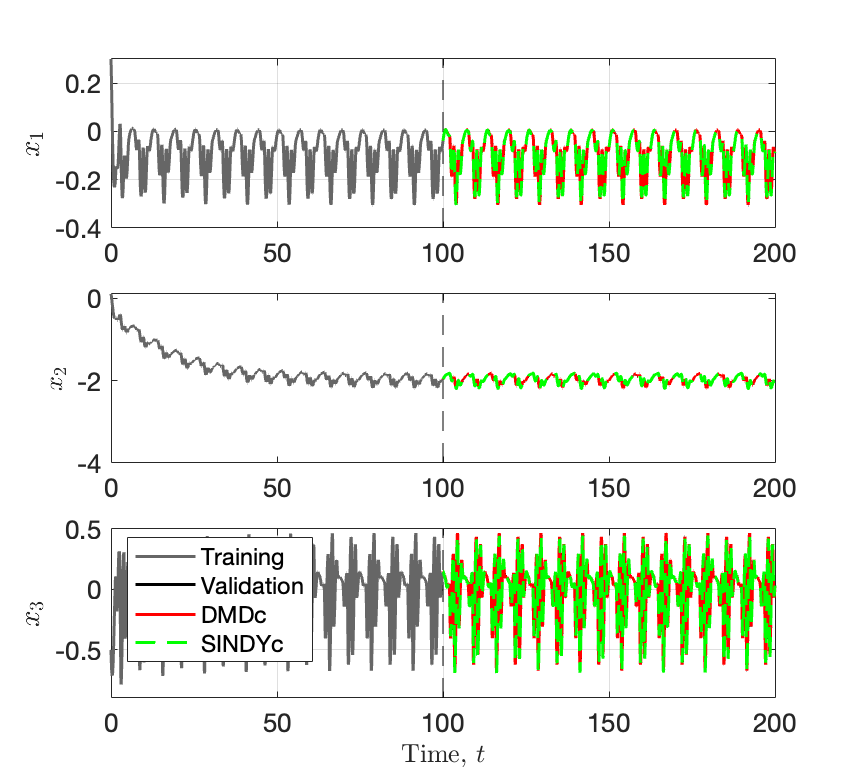

clear ph
h = figure;

% plot state 1 training data and predictions over validation phase
subplot(3,1,1), box on, hold on
plot([tB_SINDY(1) tB_SINDY(1)],[-100 100],'--k') % plot line dividing training and validation phases
plot(t, x(:,1),'Color',[.4 .4 .4],'LineWidth',1.5); % plot training data
plot(tB_Ref, xB_Ref(:,1),'k','LineWidth',1.5); % plot predictions for true reference model
plot(tB_SINDY,xB_SINDY(:,1),'r-','LineWidth',1.5); % plot predictions for SINDYc model
plot(tB_DMD, xB_DMD(:,1),'g--','LineWidth',1.5); % plot predictions for DMDc model
grid on
ylim([-0.4 0.3])
ylabel('$x_1$','FontSize',13, 'Interpreter','latex')
set(gca,'FontSize',13)

% plot state 2 training data and predictions over validation phase
subplot(3,1,2), box on, hold on
plot([tB_SINDY(1) tB_SINDY(1)],[-100 100],'--k') % plot line dividing training and validation phases
plot(t,x(:,2),'Color',[.4 .4 .4],'LineWidth',1.5); % plot training data
plot(tB_Ref, xB_Ref(:,2),'k','LineWidth',1.5); % plot predictions for true reference model
plot(tB_SINDY, xB_SINDY(:,2),'r-','LineWidth',1.5); % plot predictions for SINDYc model
plot(tB_DMD, xB_SINDY(:,2),'g--','LineWidth',1.5); % plot predictions for DMDc model
ylim([-4 0.1])
set(gca,'FontSize',13)
ylabel('$x_2$','FontSize',13, 'Interpreter','latex')

% plot state 3 training data and predictions over validation phase
subplot(3,1,3), box on, hold on
plot([tB_SINDY(1) tB_SINDY(1)],[-100 100],'--k') % plot line dividing training and validation phases
ph(1) = plot(t, x(:,3),'Color',[.4 .4 .4], 'LineWidth',1.5); % plot training data
ph(2) = plot(tB_Ref, xB_Ref(:,3),'k','LineWidth',1.5); % plot predictions for true reference model
ph(3) = plot(tB_SINDY, xB_SINDY(:,3),'r-','LineWidth',1.5); % plot predictions for SINDYc model
ph(4) = plot(tB_DMD, xB_DMD(:,3),'g--','LineWidth',1.5); % plot predictions for DMDc model
ylabel('$x_3$','FontSize',13, 'Interpreter','latex')

l1=legend(ph,'Training','Validation','DMDc','SINDYc');
set(l1,'Location','NorthWest')
grid on
ylim([-0.9 0.5])
set(gca,'FontSize',13)
xlabel('Time, $t$','FontSize',13, 'Interpreter','latex')

set(h,'Units','Inches');
set(gcf,'Position',[1 1 6. 5.5])
pos = get(h,'Position');
set(h,'PaperPositionMode','Auto','PaperSize',[pos(3), pos(4)])
print(h,'-painters','-depsc2',  '-loose','-cmyk', [figpath,'EX_',SystemModel,'_SI_Comparison_Validation_',InputSignalType,'_',InputSignalType,'.eps'],'-r0');

% plot control input trajectory
clear ph
figure,box on, hold on,
ccolors = get(gca,'colororder');

% plot the line separating training and validation phases
plot([tA(1),tA(1)],[-15 260],':','Color',[0.4,0.4,0.4],'LineWidth',1.5)

% plot the control input signal over the training phase
plot(t,u,'-k','LineWidth',1);

% plot the control input signal over the validation phase
plot(t_valid, u_valid,'-k','LineWidth',1);

grid off
ylim([min([u u_valid])+0.05*min([u u_valid]) max([u u_valid])+0.05*max([u u_valid])])
xlim([0 t_valid(end)])
xlabel('Time (s)')
ylabel('Control Input')
set(gca,'LineWidth',1, 'FontSize',14)
set(gcf,'Position',[100 100 300 200])
set(gcf,'PaperPositionMode','auto')
print('-depsc2', '-loose','-cmyk', [figpath,'EX_',SystemModel,'_SI_Comparison_Validation_',InputSignalType,'_',InputSignalType,'_Actuation.eps']);

## Model Predictive Control Simulation

Nonlinear MPC uses a nonlinear model of the dynamic system to predict how the system will evolve over a given prediction horizon and optimizes for the sequence of control inputs which will minimize a cost function $J(\mathbf{x})$ while keeping the control input within given constraints. Then it applies the first control input in the sequence (corresponding to this instance in time) and applies it to the system,

We solve the following optimization problem:


$$\min_{\mathbf{\hat{u}}(\cdot, \mathbf{x}_j)}J(\mathbf{x}_j) = \Vert \mathbf{\hat{x}}_{j + m_p} - \mathbf{x}^\star_{m_p} \Vert _{\mathbf{Q}_{m_p}}^2 + \sum_{k=0}^{m_p - 1} \Vert \mathbf{\hat{x}}_{j + k} - \mathbf{x}^\star_{k} \Vert_{\mathbf{Q}}^2 + \sum_{k=1}^{m_c - 1} \left(\Vert \mathbf{\hat{u}}_{j+k} \Vert_{\mathbf{R}_u}^2  
\Vert \Delta \mathbf{\hat{u}}_{j+k} \Vert_{\mathbf{R}_{\Delta u}}^2 \right)$$


such that:

the discrete-time system dynamics obey the given model:$\mathbf{\hat{x}}_{k + 1} = \mathbf{\hat{F}}(\mathbf{\hat{x}}_k, \mathbf{u}_k)$ 

the control inputs remain within their constraints:


$$\mathbf{u}_{\min} \le \mathbf{u}_k \le \mathbf{u}_{\max}$$


and the rate of control input change remain within their constraints:


$$\Delta \mathbf{u}_{\min} \le \Delta \mathbf{u}_k \le \Delta \mathbf{u}_{\max}$$


*The English Version: *We guess how the model will behave for some brief period into the future based on our model (using SINDYc or DMDc) and find the best way to control it over that period without breaking any of our controllers such that the angle of attack does what we want it to..

*The Goal: *Find the optimal $\mathbf{u}_k$ for each time-step $k$ over our simulation time period to track the reference state $r(t)$.

### Set up MPC Problem

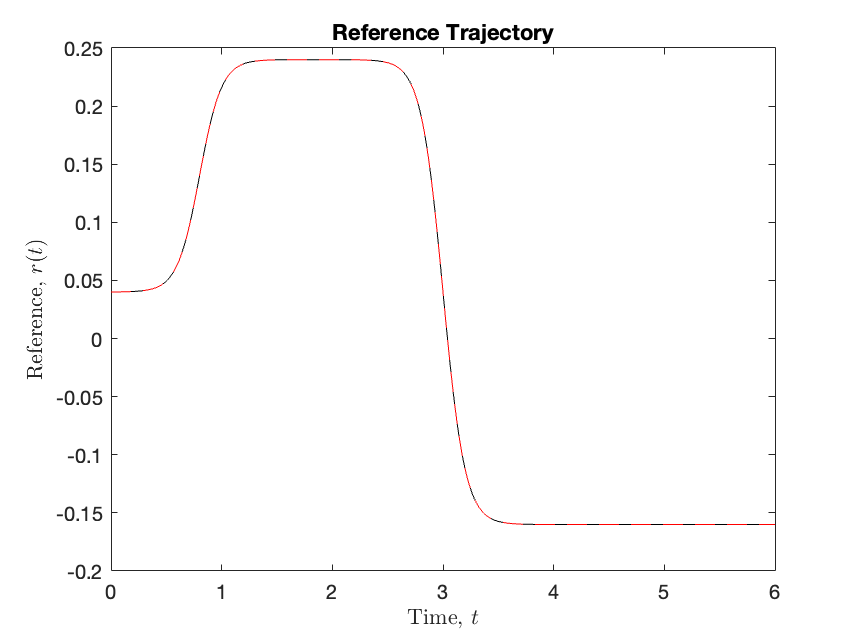

% Define parameters
dt = 0.01; % model time-step (for discretization)
options = optimoptions('fmincon','Algorithm','sqp','Display','none', ...
    'MaxIterations',100);
Duration = 6; % time to run simulation for
Ton = 0; % initial time unit when control is turned on
getMPCparams % prediction horizon, control horizon, objective function parameters, constraint parameters, reference input

x0n =[0.1 0 0]'; % initial condition
Tcontrol = tA(end);             % Time offset to combine training, prediction and control phase

% Parameters Models
ModelCollection = {'DMDc', 'SINDYc'};
Nmodels = length(ModelCollection);

Ts = Models.SINDYc.dt; % sampling time of measurements

clear Results
Results(1:Nmodels) = struct('x',[], 'u', [], 't', [], 'xref', [], 'J', [], 'elapsed_time', []);


### Run MPC Simulation

Simulation started.  It might take a while...


tElapsed = 23.7914

Simulation finished!


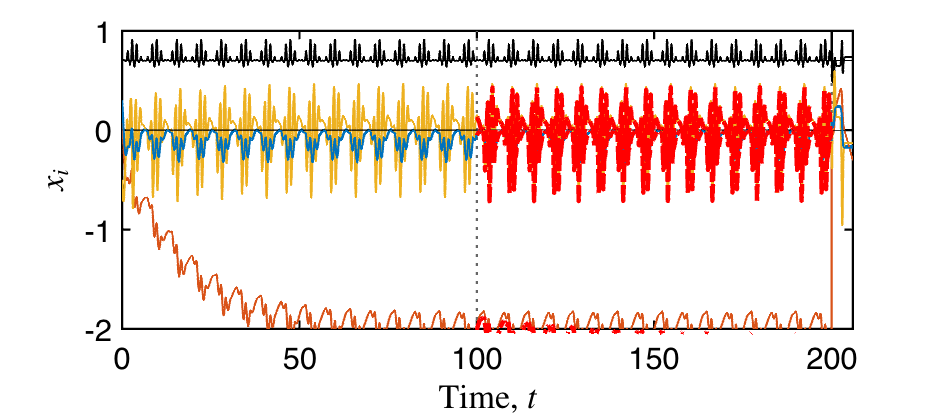

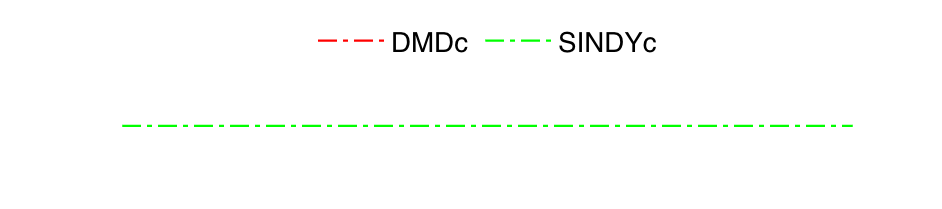

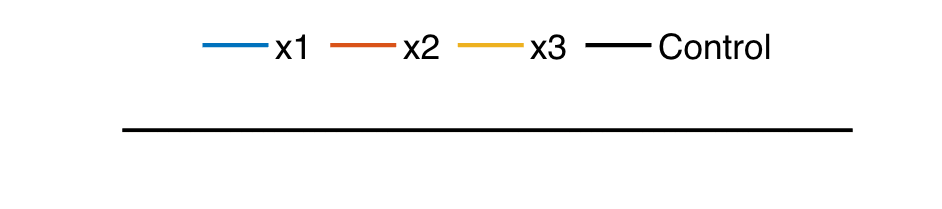

Simulation started.  It might take a while...


tElapsed = 157.3684

Simulation finished!


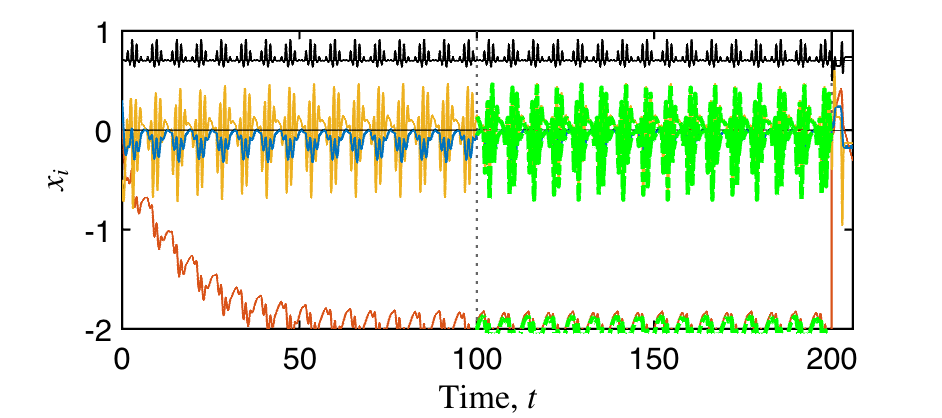

for iM = 1:Nmodels
    select_model = ModelCollection{iM};
    
    % initialize variables
    Nt       = (Duration / Ts) + 1; % number of sampling time steps to run simulation for
    uopt0    = 0; % initial u*(j+1) guess
    uopt     = uopt0 .* ones(Nu, 1);
    xhat     = x0n; % initial state estimate guess
    
    xHistory = zeros(Nvar, Nt); % trajectory of state estimates
    xHistory(:,1) = xhat;
    
    uHistory = zeros(1, Nt); % trajectory of optimal control inputs
    uHistory(1) = uopt(1);
    
    tHistory = zeros(1, Nt); % time trajectory
    tHistory(1) = 0;
    
    rHistory = zeros(1, Nt); % reference trajectory
    
    % Parameters Model
    switch select_model
        case 'DMDc'
            pest.dt = Models.DMDc.dt;
            pest.sys = Models.DMDc.sys;
            pest.xmean = Models.DMDc.xmean';
            pest.Nxlim = size(x,1);  
        case 'SINDYc'
            pest.ahat = Models.SINDYc.Xi(:,1:Nvar); % Replace with Xi0 to test true model
            pest.polyorder = Models.SINDYc.polyorder;
            pest.usesine = Models.SINDYc.usesine;
            pest.dt = Models.SINDYc.dt;
    end
    
    % Start simulation
    fprintf('Simulation started.  It might take a while...\n')
    tic

    for ct = 1:(Duration / Ts)

        % Set reference trajectory over optimization horizon
        tref = (ct:ct + N - 1) .* Ts;
        xref = [xrefFUN(tref); zeros(1, N); zeros(1, N)];

        % set cost function
        COSTFUN = @(u) ObjectiveFCN_models(u,xhat,N,Nu,xref,uHistory(:,ct),pest,diag(Q),R,Ru,select_model);

        % set constraint functions
        CONSFUN = @(u) ConstraintFCN_models(u,uHistory(:,ct),xhat,N,LBo,UBo,LBdu,UBdu,pest,select_model);
        
        % optimize for the next control input
        uopt = fmincon(COSTFUN, uopt, [], [], [], [], LB, UB, CONSFUN, options);
        
        % Run without constraints
%         uopt = fmincon(COSTFUN,uopt,[],[],[],[],[],[],[],options);   

        % Integrate system using 4th order Range-Kutta scheme to fetch resulting state estimate
        int_time_res = 10;
        xhat = rk4u(@F8Sys, xhat, uopt(1), Ts / int_time_res, int_time_res, [], 0); % Increase time resolution for simulation & keep control constant

        xHistory(:, ct + 1) = xhat; % update state trajectory
        uHistory(:, ct + 1) = uopt(1); % update optimal control input trajectory
        tHistory(:, ct + 1) = ct * Ts + Tcontrol; % update time trajectory
        rHistory(:, ct + 1) = xref(1, 2); % update reference trajectory
       
    end
    tElapsed = toc    
    fprintf('Simulation finished!\n')
    
    % Collect results
    Results(iM).eval_time = tElapsed;
    Results(iM).xref = rHistory;
    Results(iM).x = xHistory;
    Results(iM).u = uHistory;
    Results(iM).t = tHistory;
    Results(iM).J = evalObjectiveFCN(Results(iM).u,Results(iM).x,Results(iM).xref,diag(Q),R,Ru);
    Results(iM).elapsed_time = tElapsed;

    VIZ_SI_Validation_MPC
    
end

### Plot and Save Results

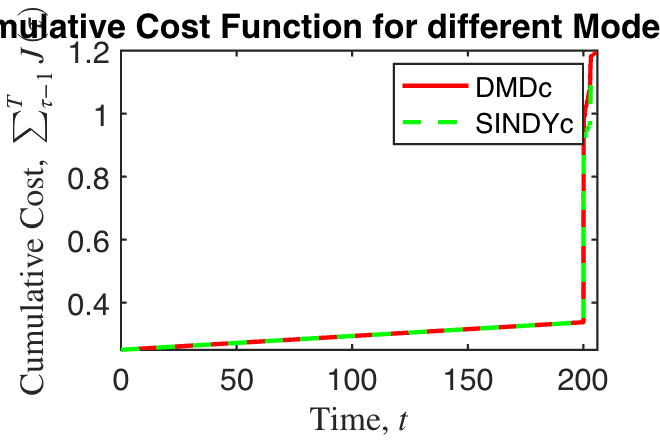

% true unforced trajectory over training phase
[tU, xU] = ode45(@(t, x) F8Sys(t, x, 0,[]), tHistory, xA(end,:), options);   % true model

% plot cumulative cost function for each model
clear ph
figure, hold on, box on
ph(1) = plot(Results(1).t, cumsum(Results(1).J),'-r','LineWidth',2);
ph(2) = plot(Results(2).t, cumsum(Results(2).J),'--g','LineWidth',2);

xlim([Results(1).t(1) Results(1).t(end)])
ylabel('Cumulative Cost, $\sum_{\tau-1}^T J(\tau)$','FontSize',14, 'Interpreter', 'latex')
xlabel('Time, $t$','FontSize',14, 'Interpreter', 'latex')
title('Cumulative Cost Function for different Model Types');
set(gca,'LineWidth',1, 'FontSize',14)
set(gcf,'Position',[100 100 300 200])
set(gcf,'PaperPositionMode','auto')
l1=legend(ph,ModelCollection{1}, ModelCollection{2});

print('-depsc2', '-loose','-cmyk', [figpath,'EX_',SystemModel,'_SI_Comparison_Validation_',InputSignalType,'_',InputSignalType,'_Cost','_N_',num2str(N),'.eps']);

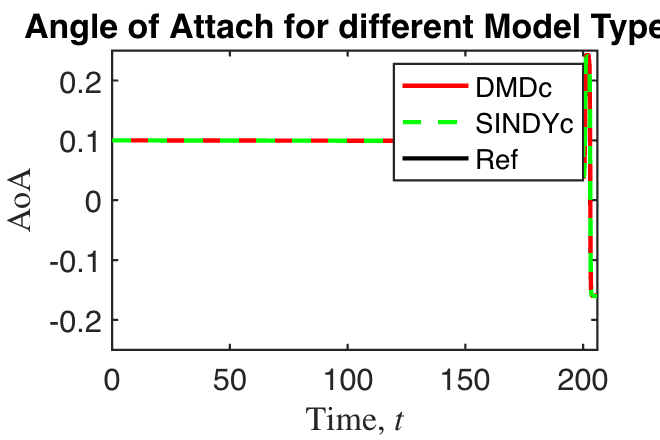

    
% plot states vs time over mpc simulation for different models with
% reference state
clear ph
figure, hold on, box on
ph(3) = plot(Results(1).t(2:end),(Results(1).xref(2:end)),'-k','LineWidth',2);
ph(1) = plot(Results(1).t,(Results(1).x(1,:)),'-r','LineWidth',2);
ph(2) = plot(Results(2).t,(Results(2).x(1,:)),'--g','LineWidth',2);
l1=legend(ph,ModelCollection{1}, ModelCollection{2}, 'Ref');
set(l1,'Location','NorthEast')
xlim([Results(1).t(1) Results(1).t(end)])
ylim([-0.25 .25])
title('Angle of Attach for different Model Types')
ylabel('AoA','FontSize',14, 'Interpreter', 'latex')
xlabel('Time, $t$','FontSize',14, 'Interpreter', 'latex')
set(gca,'LineWidth',1, 'FontSize',14)
set(gcf,'Position',[100 100 300 200])
set(gcf,'PaperPositionMode','auto')

print('-depsc2', '-loose','-cmyk', [figpath,'EX_',SystemModel,'_SI_Comparison_',InputSignalType,'_',InputSignalType,'_AoA','_N_',num2str(N),'.eps']);

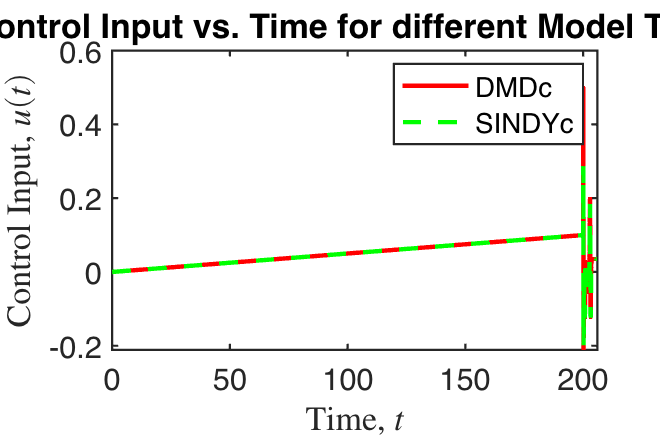


% plot optimal control input trajectory for different models
clear ph
figure, hold on, box on
ph(1) = plot(Results(1).t,(Results(1).u(:)),'-r','LineWidth',2);
ph(2) = plot(Results(2).t,(Results(2).u(:)),'--g','LineWidth',2);
xlim([Results(1).t(1) Results(1).t(end)])
ylabel('Control Input, $u(t)$','FontSize',14, 'Interpreter', 'latex')
xlabel('Time, $t$','FontSize',14, 'Interpreter', 'latex')
title('Control Input vs. Time for different Model Types')
l1=legend(ph,ModelCollection{1}, ModelCollection{2});
set(gca,'LineWidth',1, 'FontSize',14)
set(gcf,'Position',[100 100 300 200])
set(gcf,'PaperPositionMode','auto')

print('-depsc2', '-loose','-cmyk', [figpath,'EX_',SystemModel,'_SI_Comparison_',InputSignalType,'_',InputSignalType,'_Input','_N_',num2str(N),'.eps']);



% save results
save(fullfile(datapath,['MPC_',SystemModel,'_Results_AllModels_',InputSignalType,'_',InputSignalType,'_N_',num2str(N),'.mat']),'Results')
save(fullfile(datapath,['MPC_',SystemModel,'_Results_AllModels_',InputSignalType,'_',InputSignalType,'_All','_N_',num2str(N),'.mat']))